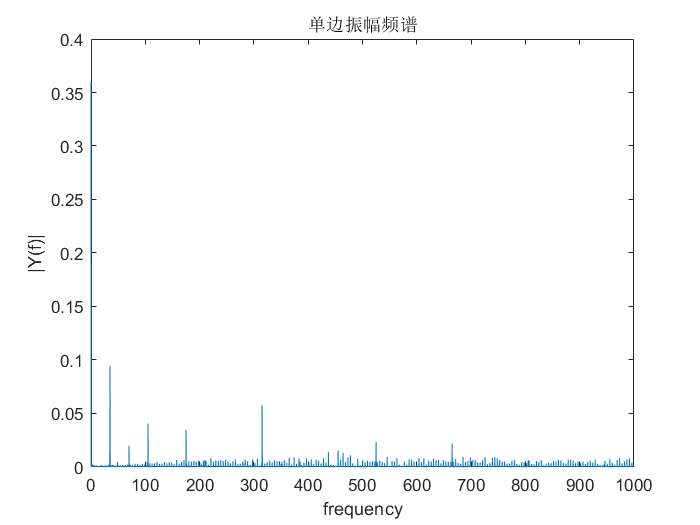

% clear
load("dist.mat");
y = data.y(50000:end);
Fs = 25000;

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 1000])

function [f, p] = fftFunc(Fs, L, y)
T= 1/Fs; %采样时间
t = (0:L-1)*T; %时间向量
NFFT = 2^nextpow2(L);
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2);
p = 2*abs(Y(1:NFFT/2));
end